## 1

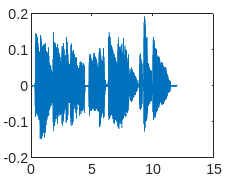


load Guitar03.mat;
%sound(x,fa);
n=length(x);
t=(0:n-1)*(1/fa);
plot(t,x);

Ta=1/fa;

## 2

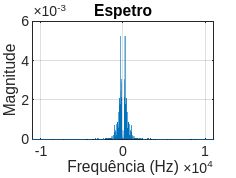


[X,f]=Espetro(x,Ta);

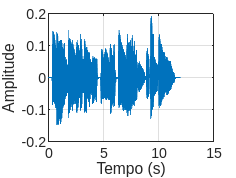

[x,t]=Reconstroi(X,f);

## 3

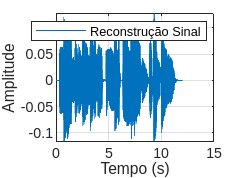

H = zeros(length(f),1);
H((f>100) & (f<400)) = 1;
H((f>-400) & (f<-100)) = 1;
xf = H.*X;
[w,t] = Reconstroi(xf,f);
legend("Reconstrução Sinal");

w = real(w);
%sound(w,fa)

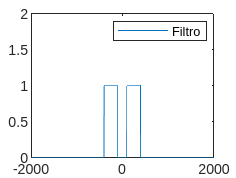

figure(2)
plot(f,H);
xlim([-2e3 2e3]);
ylim([0 2]);
legend("Filtro")

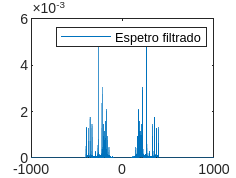

figure(3)
plot(f,abs(xf));
xlim([-1e3 1e3]);
legend("Espetro filtrado")

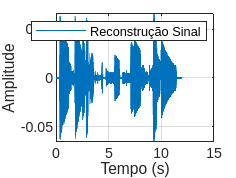

H = zeros(length(f),1);
H((f>400) & (f<600)) = 1;
H((f>-600) & (f<-400)) = 1;
xf = H.*X;
[w,t] = Reconstroi(xf,f);
legend("Reconstrução Sinal");

w = real(w);
%sound(w,fa)

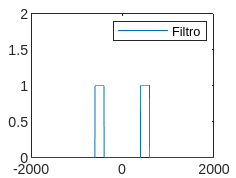

figure(4)
plot(f,H);
xlim([-2e3 2e3]);
ylim([0 2]);
legend("Filtro")

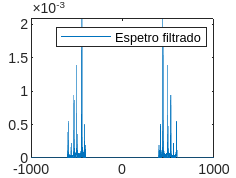

figure(5)
plot(f,abs(xf));
xlim([-1e3 1e3]);
legend("Espetro filtrado")

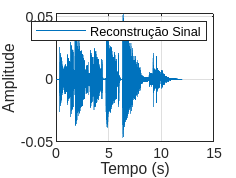

H = zeros(length(f),1);
H((f>600) & (f<1200)) = 1;
H((f>-1200) & (f<-600)) = 1;
xf = H.*X;
[w,t] = Reconstroi(xf,f);
w = real(w);
legend("Reconstrução Sinal");

%sound(w,fa)

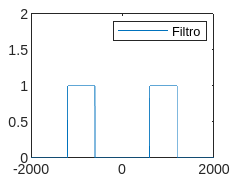

figure(6)
plot(f,H);
xlim([-2e3 2e3]);
ylim([0 2]);
legend("Filtro")

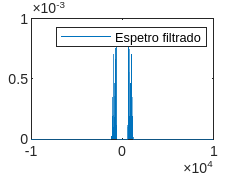

figure(7)
plot(f,abs(xf));
xlim([-1e4 1e4]);
legend("Espetro filtrado")

## II

## 1